# Phx in Live Editor

#### Figure setup

rng(0);
ax = cla; view(3); axis("equal"); camlight("headlight");
xlim([-25 25]); ylim([-25 25]); zlim([-10 40]);

% Resources directory

ans = 'C:\Users\lzhan\OneDrive\Projekty\Humusoft\PHX Toolbox\examples\phxex_catastrophy_live.mlx'

resdir = fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "res", " ");

#### Physical model

ground = phx.Body(ax, "Type", "static", "Position", [0 0 -1], "Shape", {"Box", "Size", [50 50 1]});
for i = 1:40
    clr = rand(1, 3);
    boxes(i) = phx.Body(ax, "Position", [0 0 10+i*2], "Shape", {"Box", "Size", rand(1, 3)*5, "Color", clr});
    phx.Trace(boxes(i), "TracePoints", 50, "Color", clr);
end
shape = phx.shape.STL("Source", resdir+"cat.stl", "Scale", 0.1, "Details", 0.5, "Color", [1 1 1]);
for i = 1:10
    cats(i) = phx.Body(ax, "Position", [rand*40-20 rand*40-20 5], "Shape", shape);
end

#### Simulation

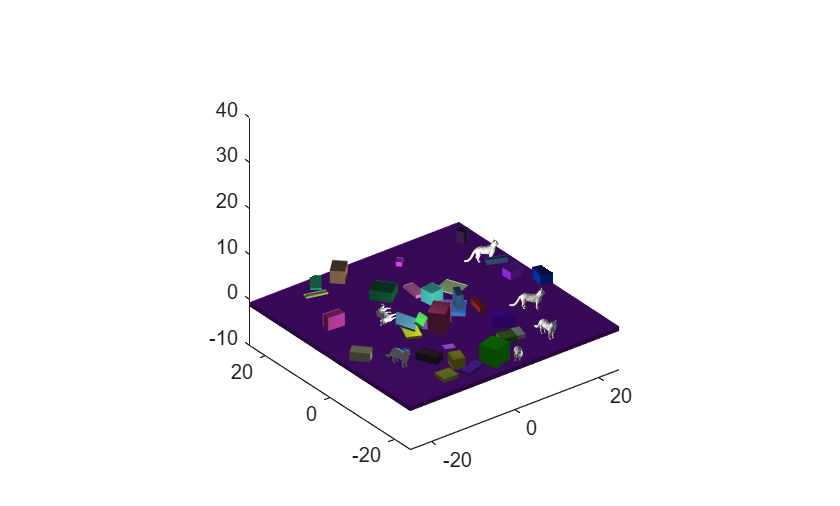

sim = phx.Simulation([ground boxes cats]);
sim.step(20, 2000, 10);
delete(sim);